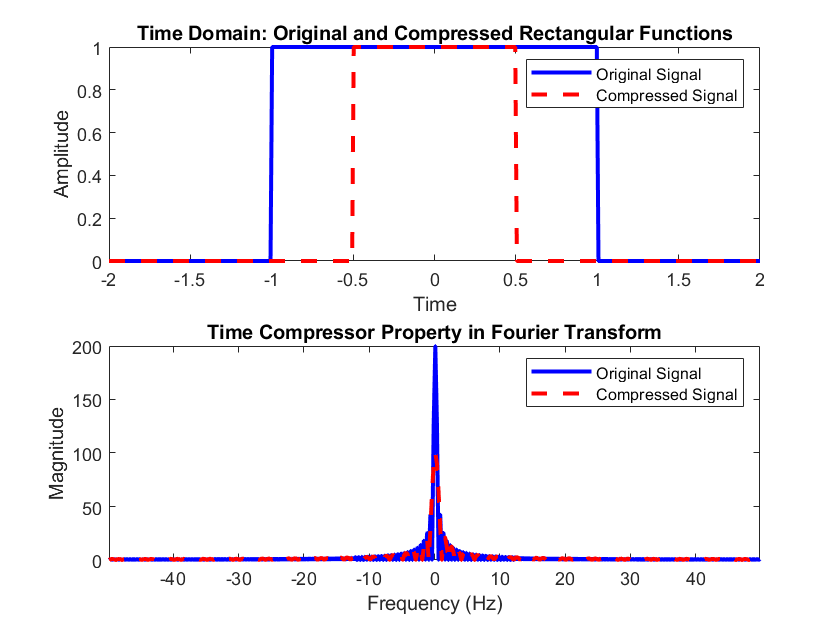

% Time compressor property in Fourier transform of rect function

% Define parameters
T = 1;          % Period of the rectangular function
t = linspace(-2*T, 2*T, 400); % Time vector with 400 points
a = 0.5;        % Compression factor

% Original rectangular function
x_original = rectangularPulse(-T, T, t);

% Time-compressed rectangular function
x_compressed = rectangularPulse(-a*T, a*T, t);

% Fourier transform of original signal
X_original = fftshift(fft(x_original));

% Fourier transform of compressed signal
X_compressed = fftshift(fft(x_compressed));

% Frequency vector
Fs = 1/(t(2)-t(1)); % Sampling frequency
f = linspace(-Fs/2, Fs/2, length(t));

% Create a new figure
figure;

% Plotting the original and compressed signals in the time domain
subplot(2,1,1);
plot(t, x_original, 'b', 'LineWidth', 2);
hold on;
plot(t, x_compressed, 'r--', 'LineWidth', 2);
hold off;
title('Time Domain: Original and Compressed Rectangular Functions');
legend('Original Signal', 'Compressed Signal');
xlabel('Time');
ylabel('Amplitude');
xlim([-2*T, 2*T]); % Setting x-axis limits

% Plotting the original and compressed signals in the frequency domain
subplot(2,1,2);
plot(f, abs(X_original), 'b', 'LineWidth', 2);
hold on;
plot(f, abs(X_compressed), 'r--', 'LineWidth', 2);
hold off;
title('Frequency Domain: Fourier Transforms');
legend('Original Signal', 'Compressed Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([-Fs/2, Fs/2]); % Setting x-axis limits

% Adjusting subplot layout
title('Time Compressor Property in Fourier Transform', 'FontSize', 14);